# **Velocity Profile Generation Using Trapezoidal Profile**

The script generates the reference velocity based on the following methods: 

- **Basic trapezoidal profile: **Trapezoidal velocity profile takes inspiration from robotics, where the movement as well as the track parameters are ideal. Few tweaks and additions to the robotic trapezoidal profile can be very well used to generate a velocity profile for a race car on a track. *Use the trapezoidal profile when the track parameters as well as vehicle parameters are close to ideal.*

- **Radius of curvature and friction based trapezoidal  profile: **The radius of curvature feature is an addition to the trapezoidal profile. It restricts the maximum velocity of the vehicle at curved roads. This feature is not inclusive of the trapezoidal function as robots would always stop at intersections and accelerate linearly after changing the direction. *Use this function with tracks with multiple curves. *

- **Maximum velocity and acceleration based trapezoidal profile: **The braking and acceleration feature gives more freedom to the user to set the maximum stable velocity and maximum acceleration that can be attained by the vehicle.  *Use this feature to remove excessive jerks and infinitesimal acceleration/deceleration from the velocity profile.  *

#### How to use the script?

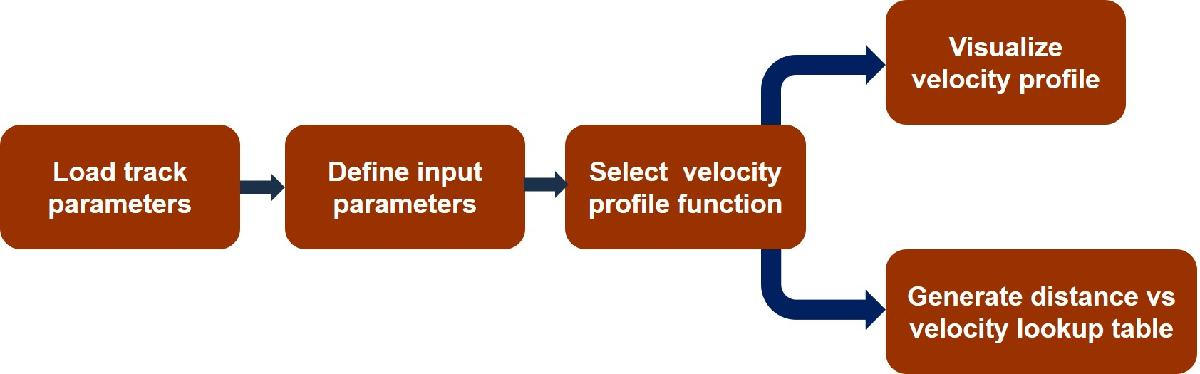

#### Input Parameters 

load('UScityblock2.mat');     % load track parameters                  
wayp = data.ActorSpecifications(1,1).Waypoints; % define waypoints
maxvel = 20;  % user defined maximum velocity input (m/s)
maxacc = 0.8;  % user defined maximum acceleration input (m/s^2)
brkgain = 0.8; % braking gain
nst     = 1; % number of sharp turns

#### Select Velocity Profile Function

[poscmp,poslt,velmap,vel,ts] = basictrap(wayp,maxvel,nst); % Select the function to generate the velocity profile


#### **Distance and Velocity Calculation for Simulink Lookup Table**

xRef = wayp(:,1);
yRef = -wayp(:,2);
X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction

poslt_xy = [poslt(1,:)' poslt(2,:)']; % extract the vehicle x and y values
distancematrix = squareform(pdist(poslt_xy));
distancesteps = zeros(length(poslt_xy)-1,1);
for i = 2:length(poslt_xy)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
dislt = cumsum([0; distancesteps]) + sqrt((X_o).^2+(Y_o).^2) - 5; % distance at each time step
distancecovered = dislt(end);
velt_res = vel(4,:); % vehicle resultant velocity (m/s)

% The vehicle starts with a zero velociy. 
% Hence, to define an initial non-zero velocity first 6 rows are replaced
% by the value in the 7th row. Please feel free to comment out this if you want
% to start the vehicle with zero velocity
velt_res(1:6) = velt_res(7); 

#### Plots

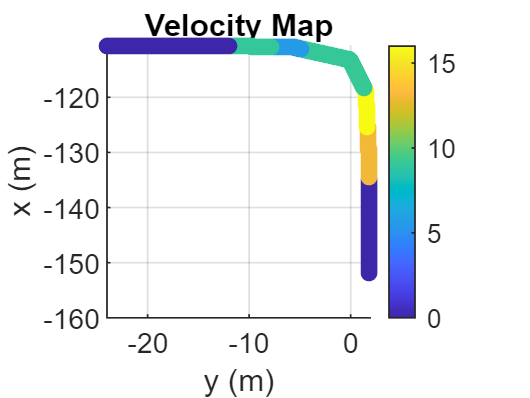

x = poscmp(1,:);
y = -poscmp(2,:);
sz = 25;
c = velmap(4,:);
scatter(y,x,sz,c,'filled')
colorbar
grid
xlabel('y (m)')
ylabel('x (m)')
title('Velocity Map')

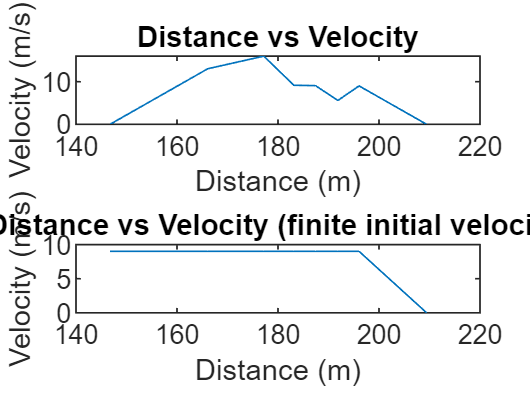


subplot(2,1,1)
plot(dislt, vel(4,:))
xlabel('Distance (m)')
ylabel('Velocity (m/s)')
title('Distance vs Velocity')

subplot(2,1,2)
plot(dislt, velt_res)
xlabel('Distance (m)')
ylabel('Velocity (m/s)')
title('Distance vs Velocity (finite initial velocity)')

#### Basic Trapezoidal Velocity Profile Function

function [poscmp,poslt,velmap,vel,ts] = basictrap(wayp,maxvel,nst)
% posmp = vehicle position for colormap (m)
% poslt = vehicle position for lookup table (m)
% velmap = vehicle velocity after dividing tracks into multiple segments. (m/s)
% This output has been used for colormap.
% vel = vehicle velocity (m/s)
% tvec = sample time (s)
% wayp = waypoints;
% maxvel = vehicle maximum velocity (m/s)
% nst = number of sharp turns

wayp=wayp'; % waypoints
nwayp=height(wayp'); % number of waypoints
[poscmp, velmap, ~, ~, ~] = trapveltraj(wayp,1000*(nwayp+nst)); % calculate trapezoidal parameters
[poslt, vel, ~,ts, ~] = trapveltraj(wayp,(nwayp+nst));
vel(4,:)= sqrt(vel(1,:).^2 + vel(2,:).^2 + vel(3,:).^2); % calculate magnitude of velocity


for j=1:nwayp+nst % maximum velocity filter
    if vel(4,j)>maxvel
       vel(4,j) = maxvel; 
    end
end

for i=1:nwayp+nst
    velmap(4,1000*(i-1)+1:1000*i) = vel(4,i);
end
end



#### **Radius of Curvature and Friction Based Trapezoidal Velocity Profile **Function

function [poscmp,poslt,velmap,vel,ts] = radfrictrap(wayp,maxvel,nst)
% posmp = vehicle position for colormap (m)
% poslt = vehicle position for lookup table (m)
% velmap = vehicle velocity after diving tracks into multiple segments. (m/s)
% This output has been used for colormap.
% vel = vehicle velocity (m/s)
% ts = sample time (s)
% wayp = waypoints;
% maxvel = vehicle maximum velocity (m/s)
% nst = number of sharp turns

wayp=wayp'; % waypoints
nop=height(wayp'); % number of waypoints
[poscmp, velmap, ~, ~, ~] = trapveltraj(wayp,1000*(nop+nst)); % calculate trapezoidal parameters
[poslt, vel, ~,ts, ~] = trapveltraj(wayp,(nop+nst));
vel(4,:)= sqrt(vel(1,:).^2 + vel(2,:).^2 + vel(3,:).^2); %calculate magnitude of velocity

r = zeros(1,nop+nst);
for j=2:nop %calculate radius of curvature at each given waypoint
    r(1,j) = radius(poscmp(1,j-1),poscmp(2,j-1),poscmp(1,j),poscmp(2,j),poscmp(1,j+1),poscmp(2,j+1));
end

fric = 0.7; % coefficient of friction
velmax=zeros(1,nop+nst); 

for k = 1:nop+1 %calculate maximum vehicle velocity at a point using the curvature and friction of coefficient
    velmax(1,k)=sqrt(fric*9.81*r(1,k));
    if velmax(1,k) < vel(4,k)
        vel(4,k)=velmax(1,k);
    end
end


for j=1:nop+nst
    if vel(4,j)>maxvel
       vel(4,j) = maxvel; 
    end
end


for i=1:nop+nst
    velmap(4,1000*(i-1)+1:1000*i) = vel(4,i);
end
end


#### Maximum Velocity and Acceleration Based Velcoity Profile Function

function [poscmp,poslt,velmap,vel,ts] = maxvelacctrap(wayp,maxvel,maxacc,nst,brkgain)
% posmp = vehicle position for colormap (m)
% poslt = vehicle position for lookup table (m)
% velmap = vehicle velocity after diving tracks into multiple segments. (m/s)
% This output has been used for colormap.
% vel = vehicle velocity (m/s)
% ts = sample time (s)
% wayp = waypoints;
% maxvel = vehicle maximum velocity (m/s)
% nst = number of sharp turns
% brkgain = braking gain;

wayp=wayp'; % waypoints
nop=height(wayp'); % number of waypoints
[poscmp, velmap, ~, ~, ~] = trapveltraj(wayp,1000*(nop+nst));  % calculate trapezoidal parameters by maximum splitting
[poslt, vel, ~, ts, ~] = trapveltraj(wayp,(nop+nst));         % calculate trapezoidal parameters
vel(4,:)= sqrt(vel(1,:).^2 + vel(2,:).^2 + vel(3,:).^2);  % calculate magnitude of velocity

for j= 2:nop+nst   % braking correction
    vel(4,j) = brkgain*(vel(4,j-1)+vel(4,j));
end

for j=1:nop+nst   % maximum velocity filter
    if vel(4,j)>maxvel
       vel(4,j) = maxvel; 
    end
end


for j=2:nop+nst    % maximum acceleration filter
    if vel(4,j) - vel(4,j-1) > maxacc
        vel(4,j) = vel(4,j-1)+maxacc;
    end        
end

for i=1:nop+nst    % Create multiple waypoints for track simulation
    velmap(4,1000*(i-1)+1:1000*i) = vel(4,i);
end
end